# 6.5 设计全流程与对比：同一指标的四种设计（巴特沃思/切比雪夫 × 脉冲响应不变/双线性），再做一道 Hz 指标的题

在 MATLAB 编辑器中打开，点击“运行”；或逐节运行。全部用本章自写的 dsp_* 函数，有工具箱时与 buttord/cheb1ord 对照。

clearvars;
LIVE = strcmp(getenv('DSP_LIVE'), '1');
if LIVE, newpanel = @(varargin) figure('Color','w','Position',[80 80 640 420]); else, newpanel = @(varargin) nexttile(varargin{:}); end
if LIVE, set(groot, 'defaultLegendLocation', 'southoutside'); else, set(groot, 'defaultLegendLocation', 'best'); end
here = fileparts(mfilename('fullpath')); if endsWith(here, 'mlx'), here = fileparts(here); end
if ~exist(fullfile(here, 'dsp_freqz.m'), 'file'), here = fileparts(which('dsp_freqz')); end   % Live Script 里 mfilename 为空时靠路径找
codedir = here; addpath(codedir); outdir = fullfile(codedir, 'results'); if ~exist(outdir, 'dir'), mkdir(outdir); end

## 指标（教材例 6.5 / 6.8）：ωp=0.2π 处 ≤1 dB，ωs=0.3π 处 ≥15 dB，T=1

wp = 0.2*pi; ws = 0.3*pi; ap = 1; as = 15; T = 1;
eps = sqrt(10^(ap/10) - 1);
names = {'巴特沃思 + 脉冲响应不变', '巴特沃思 + 双线性', '切比雪夫 + 脉冲响应不变', '切比雪夫 + 双线性'};
BZ = cell(1, 4); AZ = cell(1, 4); Nord = zeros(1, 4);
% (1) 巴特沃思 + 脉冲响应不变：Ω=ω/T
Nb = ceil(log10((10^(as/10) - 1)/(10^(ap/10) - 1))/(2*log10(ws/wp))); Wc = (wp/T)/(10^(ap/10) - 1)^(1/(2*Nb));
[bA, aA] = dsp_butter_analog(Nb, Wc); [BZ{1}, AZ{1}] = dsp_impinvar(bA, aA, T); Nord(1) = Nb;
% (2) 巴特沃思 + 双线性：先预畸变
Wp2 = (2/T)*tan(wp/2); Ws2 = (2/T)*tan(ws/2);
Nb2 = ceil(log10((10^(as/10) - 1)/(10^(ap/10) - 1))/(2*log10(Ws2/Wp2))); Wc2 = Wp2/(10^(ap/10) - 1)^(1/(2*Nb2));
[bA, aA] = dsp_butter_analog(Nb2, Wc2); [BZ{2}, AZ{2}] = dsp_bilinear(bA, aA, T); Nord(2) = Nb2;
% (3) 切比雪夫 + 脉冲响应不变
Nc = ceil(acosh(sqrt(10^(as/10) - 1)/eps)/acosh(ws/wp));
[bA, aA] = dsp_cheby1_analog(Nc, eps, wp/T); [BZ{3}, AZ{3}] = dsp_impinvar(bA, aA, T); Nord(3) = Nc;
% (4) 切比雪夫 + 双线性
Nc2 = ceil(acosh(sqrt(10^(as/10) - 1)/eps)/acosh(Ws2/Wp2));
[bA, aA] = dsp_cheby1_analog(Nc2, eps, Wp2); [BZ{4}, AZ{4}] = dsp_bilinear(bA, aA, T); Nord(4) = Nc2;
% 指标核对：相对各自的最大幅度
w = linspace(0, pi, 2048); H = zeros(4, numel(w)); att = zeros(4, 2); gd = zeros(4, numel(w) - 1);
for i = 1:4
    H(i, :) = dsp_freqz(BZ{i}, AZ{i}, w); Hmax = max(abs(H(i, :)));
    att(i, :) = -20*log10(abs(dsp_freqz(BZ{i}, AZ{i}, [wp ws]))/Hmax);
    ph = unwrap(angle(H(i, :))); gd(i, :) = -diff(ph)./diff(w);      % 群延迟 −dθ/dω（数值微分）
end
gdRange = zeros(1, 4); for i = 1:4, g = gd(i, w(1:end-1) <= wp); gdRange(i) = max(g) - min(g); end   % 通带内群延迟起伏
errOrd = NaN;
if exist('buttord', 'file') == 2 && exist('cheb1ord', 'file') == 2
    [n1, ~] = buttord(Wp2, Ws2, ap, as, 's'); [n2, ~] = cheb1ord(Wp2, Ws2, ap, as, 's'); errOrd = max(abs([n1 - Nb2, n2 - Nc2]));
end

## 习题 11 型：fs=200 Hz，0≤f≤25 Hz 衰减 <3 dB，f≥50 Hz 衰减 ≥38 dB，巴特沃思 + 双线性

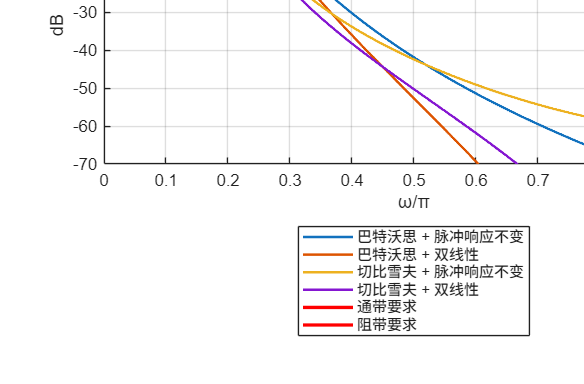

fs = 200; fp = 25; fst = 50; apH = 3; asH = 38; Th = 1/fs;
wpH = 2*pi*fp/fs; wsH = 2*pi*fst/fs;                                   % 0.25π、0.5π
WpH = (2/Th)*tan(wpH/2); WsH = (2/Th)*tan(wsH/2);
NH = ceil(log10((10^(asH/10) - 1)/(10^(apH/10) - 1))/(2*log10(WsH/WpH)));
WcH = WpH/(10^(apH/10) - 1)^(1/(2*NH));
[bA, aA] = dsp_butter_analog(NH, WcH); [bzH, azH] = dsp_bilinear(bA, aA, Th);
fHz = linspace(0, fs/2, 1024); HH = dsp_freqz(bzH, azH, 2*pi*fHz/fs);
attH = -20*log10(abs(dsp_freqz(bzH, azH, [wpH wsH])));

if ~LIVE, f1 = figure('Name','05 设计对比','Color','w','Position',[60 40 1250 900]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
newpanel(); hold on;
for i = 1:4, plot(w/pi, 20*log10(abs(H(i, :))/max(abs(H(i, :)))), 'LineWidth', 1.5); end
plot([0 wp/pi], [-ap -ap], 'r-', 'LineWidth', 2); plot([ws/pi 1], [-as -as], 'r-', 'LineWidth', 2);
grid on; ylim([-70 3]); xlabel('ω/π'); ylabel('dB');
title(sprintf('① 同一指标的四种设计：阶数 %d/%d/%d/%d；ω_s 处衰减 %.1f/%.1f/%.1f/%.1f dB', Nord, att(:, 2)));
legend([names, {'通带要求', '阻带要求'}]);

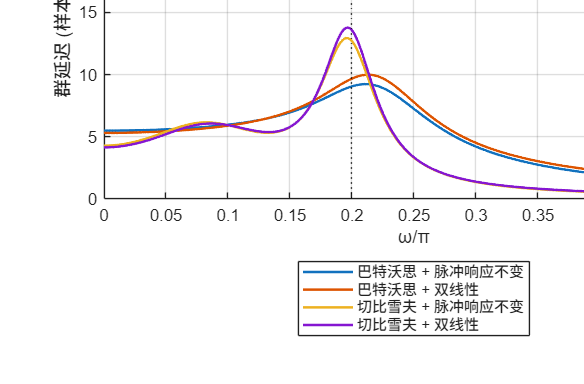

newpanel(); hold on;
for i = 1:4, plot(w(1:end-1)/pi, gd(i, :), 'LineWidth', 1.5); end
xline(wp/pi, 'k:'); grid on; xlabel('ω/π'); ylabel('群延迟 (样本)'); xlim([0 0.5]); ylim([0 25]);
title(sprintf('② 群延迟：通带内起伏 %.1f/%.1f/%.1f/%.1f 个样本——切比雪夫更陡也更“不平”', gdRange));
legend(names);

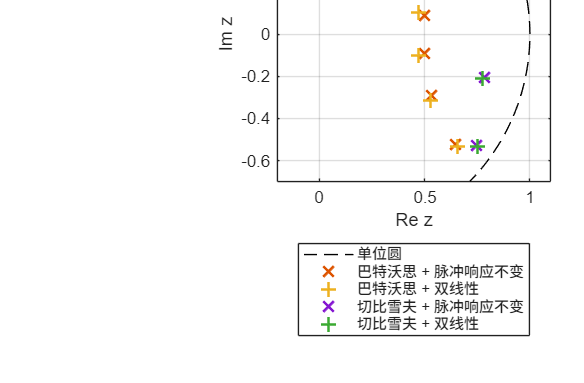

newpanel(); tt = linspace(0, 2*pi, 400); plot(cos(tt), sin(tt), 'k--'); hold on; axis equal; grid on;
mk = {'x', '+', 'x', '+'};
for i = 1:4, pz = roots(AZ{i}); plot(real(pz), imag(pz), mk{i}, 'MarkerSize', 9, 'LineWidth', 1.5); end
xlim([-0.2 1.1]); ylim([-0.7 0.7]); xlabel('Re z'); ylabel('Im z');
title('③ 四种设计的极点：都在单位圆内；切比雪夫的极点更靠近单位圆');
legend(['单位圆', names]);

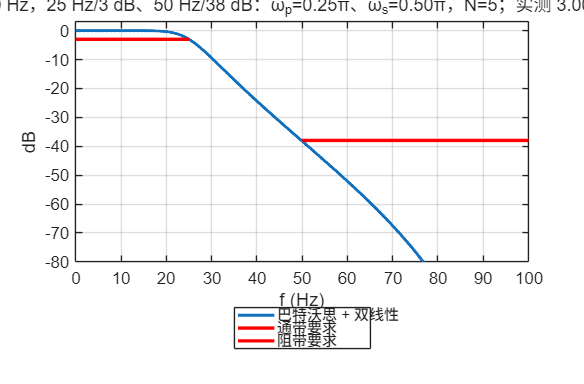

newpanel(); plot(fHz, 20*log10(abs(HH)), 'LineWidth', 1.8); hold on;
plot([0 fp], [-apH -apH], 'r-', 'LineWidth', 2); plot([fst fs/2], [-asH -asH], 'r-', 'LineWidth', 2);
grid on; ylim([-80 3]); xlabel('f (Hz)'); ylabel('dB');
title(sprintf('④ f_s=200 Hz，25 Hz/3 dB、50 Hz/38 dB：ω_p=%.2fπ、ω_s=%.2fπ，N=%d；实测 %.2f、%.1f dB', wpH/pi, wsH/pi, NH, attH));
legend('巴特沃思 + 双线性', '通带要求', '阻带要求');

if ~LIVE, sgtitle('从指标到 H(z)：定原型、定阶、定 Ω_c、变换、核对；四条路都能达标，差别在阶数、相位和混叠'); end
if ~LIVE, prepare_export(f1); end
if ~LIVE, exportgraphics(f1, fullfile(outdir, '05-iir-design-compare.png'), 'Resolution', 150); end

## 教师核验

assert(isequal(Nord, [6 6 4 4]), '阶数与预期不符');
assert(all(att(:, 1) <= ap + 0.05) && all(att(:, 2) >= as - 0.5), '四种设计的指标核验不符');
assert(all(cellfun(@(a) max(abs(roots(a))) < 1, AZ)), '应全部稳定');
assert(NH >= 1 && attH(1) <= apH + 1e-6 && attH(2) >= asH, '习题 11 型设计不达标');
assert(isnan(errOrd) || errOrd == 0, '与 buttord/cheb1ord 不符');
metrics = struct('matlab_version', version, 'run_at', char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')), ...
    'orders', Nord, 'att_wp_dB', att(:, 1).', 'att_ws_dB', att(:, 2).', 'groupdelay_ripple_passband', gdRange, 'max_pole_radius', cellfun(@(a) max(abs(roots(a))), AZ), ...
    'err_vs_buttord_cheb1ord', errOrd, 'hw11_wp_ws_over_pi', [wpH wsH]/pi, 'hw11_prewarped_Wp_Ws', [WpH WsH], 'hw11_N', NH, 'hw11_Wc', WcH, 'hw11_bz', bzH, 'hw11_az', azH, 'hw11_att_dB', attH, ...
    'all_checks_passed', true);
fid = fopen(fullfile(outdir, 'verification-iir-design-compare.json'), 'w', 'n', 'UTF-8'); assert(fid >= 0);
fprintf(fid, '%s\n', jsonencode(metrics, PrettyPrint=true)); fclose(fid);
disp(metrics); fprintf('\n课堂图已保存到：%s\n', outdir);

                matlab_version: '25.2.0.3360999 (R2025b) Update 7'
                        run_at: '2026-09-18 21:31:49'
                        orders: [6 6 4 4]
                     att_wp_dB: [0.9999 1.0000 1.0005 1.0000]
                     att_ws_dB: [15.3903 17.6537 21.5790 23.6074]
    groupdelay_ripple_passband: [3.5516 4.3580 8.6469 9.6310]
               max_pole_radius: [0.8336 0.8455 0.9161 0.9210]
       err_vs_buttord_cheb1ord: 0
            hw11_wp_ws_over_pi: [0.2500 0.5000]
          hw11_prewarped_Wp_Ws: [165.6854 400.0000]
                        hw11_N: 5
                       hw11_Wc: 165.7641
                       hw11_bz: [0.0033 0.0164 0.0329 0.0329 0.0164 0.0033]
                       hw11_az: [1 -2.4733 2.8091 -1.7023 0.5439 -0.0722]
                   hw11_att_dB: [3.0000 38.2576]
             all_checks_passed: 1


课堂图已保存到：G:\2026-Agent\数字信号处理\课程网站\ch6\code\results



function prepare_export(fig)
axesList = findall(fig, 'Type', 'axes');
for a = 1:numel(axesList), axesList(a).Toolbar.Visible = 'off'; end
drawnow;
end